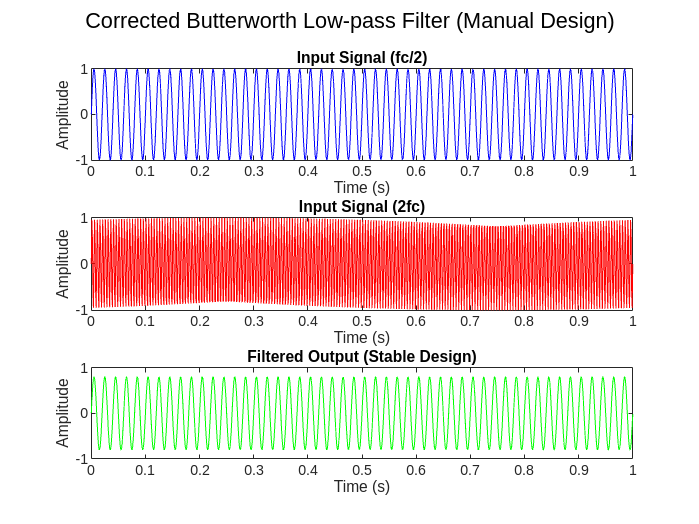

clc; clear; close all;

% Define filter specifications
order = 3;         % Filter order
fc = 10;          % Cutoff frequency in Hz
fs = 1000;         % Sampling frequency in Hz
T = 1/fs;          % Sampling period

% Generate time vector
t = linspace(0, 1, fs);

% Generate input signals
sig1 = sin(2 * pi * (fc / 2) * t);  % Signal with frequency fc/2
sig2 = sin(2 * pi * (2 * fc) * t);  % Signal with frequency 2fc            

%% Butterworth Filter Design (Manually)
% Pre-warp the frequency for bilinear transformation
omega_c = 2 * pi * fc; 
omega_s = 2 * fs * tan(omega_c / (2 * fs)); % Correct pre-warped analog frequency

% Compute Butterworth poles in the s-domain
poles_s = omega_s * exp(1j * pi * (1:2:2*order-1) / (2*order));

% Convert analog poles to digital domain using bilinear transform
poles_z = (1 + poles_s * T / 2) ./ (1 - poles_s * T / 2);

% Ensure the poles are inside the unit circle for stability
poles_z = poles_z(abs(poles_z) < 1);

% Compute denominator coefficients from stable poles
den = real(poly(poles_z)); 

% Compute numerator to normalize gain at DC (ensuring H(0) = 1)
num = sum(den);

% Apply filter using filtfilt (zero-phase filtering)
filtered_sig1 = filtfilt(num, den, sig1);
filtered_sig2 = filtfilt(num, den, sig2);

% Plot the input and filtered signals
figure;
subplot(3,1,1);
plot(t, sig1, 'b');
title('Input Signal (fc/2)');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(3,1,2);
plot(t, sig2, 'r');
title('Input Signal (2fc)');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(3,1,3);
plot(t, filtered_sig1, 'g');
title('Filtered Output (Stable Design)');
xlabel('Time (s)');
ylabel('Amplitude');

sgtitle('Corrected Butterworth Low-pass Filter (Manual Design)');

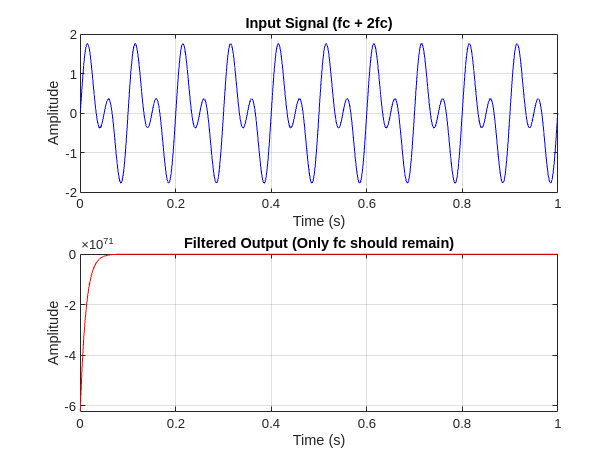

clc; clear; close all;

%% Define Filter Specifications
order = 3;   % Filter order
fc = 10;     % Cutoff frequency in Hz
fs = 1000;   % Sampling frequency in Hz
T = 1/fs;    % Sampling period

%% Generate Time Vector
t = linspace(0, 1, fs);  % 1 second duration

%% Generate Input Signals
sig1 = sin(2 * pi * fc * t);     % Signal with frequency fc
sig2 = sin(2 * pi * 2 * fc * t); % Signal with frequency 2fc
x = sig1 + sig2;  % Combined input signal

%% Butterworth Filter Design (Manual)
% Pre-warp cutoff frequency for bilinear transformation
omega_c = 2 * pi * fc;
omega_w = 2 * fs * tan(omega_c / (2 * fs)); % Pre-warped cutoff frequency

% Compute Butterworth poles in the s-domain
poles_s = omega_w * exp(1j * pi * (1:2:2*order-1) / (2*order));

% Convert analog poles to digital using bilinear transform
poles_z = (1 + poles_s * T / 2) ./ (1 - poles_s * T / 2);

% Compute denominator coefficients from poles
den = real(poly(poles_z));

% Compute numerator to normalize gain at DC
num = sum(den) / den(1);  % Correct scaling

%% Apply Filter
y = filtfilt(num, den, x);  % Zero-phase filtering to remove delay

%% Plot Input and Output Signals
figure;
subplot(2,1,1);
plot(t, x, 'b');
title('Input Signal (fc + 2fc)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

subplot(2,1,2);
plot(t, y, 'r');
title('Filtered Output (Only fc should remain)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

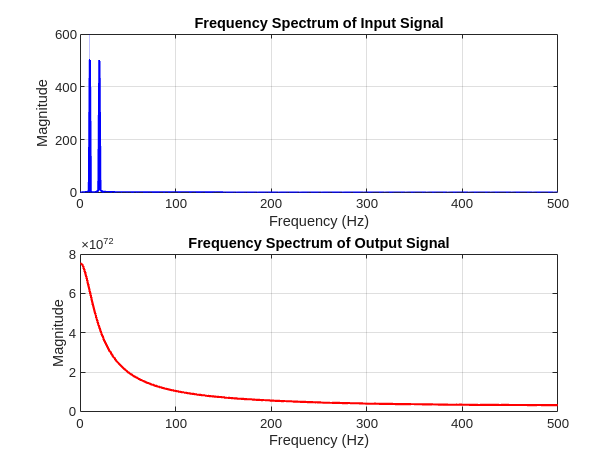


%% Frequency Domain Analysis
NFFT = length(t);
X_f = abs(fft(x, NFFT));  % FFT of input signal
Y_f = abs(fft(y, NFFT));  % FFT of output signal
f_axis = (0:NFFT-1) * (fs/NFFT);  % Frequency axis

figure;
subplot(2,1,1);
plot(f_axis, X_f, 'b', 'LineWidth', 1.5);
title('Frequency Spectrum of Input Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
xlim([0 fs/2]);
grid on;

subplot(2,1,2);
plot(f_axis, Y_f, 'r', 'LineWidth', 1.5);
title('Frequency Spectrum of Output Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
xlim([0 fs/2]);
grid on;

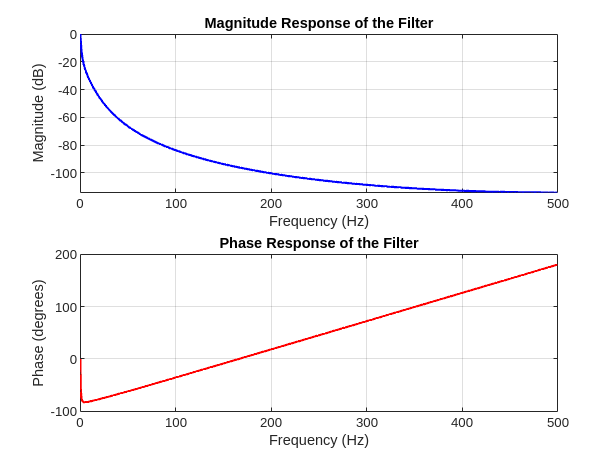


%% Plot Filter Frequency Response
figure;
[H, w] = freqz(num, den, 1024, fs); % Compute frequency response
subplot(2,1,1);
plot(w, 20*log10(abs(H)), 'b', 'LineWidth', 1.5);
title('Magnitude Response of the Filter');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;

subplot(2,1,2);
plot(w, angle(H) * (180/pi), 'r', 'LineWidth', 1.5);
title('Phase Response of the Filter');
xlabel('Frequency (Hz)');
ylabel('Phase (degrees)');
grid on;

clear; close all; clc;

% Define filter specifications
order = 3;         % Keep filter order 3
Fc = 10;           % Cutoff frequency in Hz
Fs = 1000;         % Sampling frequency in Hz
Ts = 1 / Fs;       % Sampling period

% Prewarp the cutoff frequency for bilinear transform
omega_c = 2 * pi * Fc;  
omega_c_d = 2 * Fs * tan(omega_c / (2 * Fs));  

% Compute Butterworth poles in s-domain
poles = zeros(order, 1);
for k = 1:order
    theta = (2 * k + order - 1) * pi / (2 * order);
    poles(k) = omega_c_d * exp(1j * theta);
end

% Convert s-domain poles to z-domain using bilinear transform
poles_z = (1 + poles * Ts / 2) ./ (1 - poles * Ts / 2);

% Compute filter denominator coefficients
a = poly(poles_z);

% Compute numerator coefficients (gain normalization)
b = sum(a);

% Generate time vector
t = linspace(0, 1, Fs);  

% Generate input signals
signal1 = sin(2 * pi * (Fc / 2) * t);  % Low-frequency component
signal2 = sin(2 * pi * (2 * Fc) * t);  % High-frequency component

% Combine both signals
combined_signal = signal1 + signal2;

% Apply custom zero-phase filtering
filtered_signal = myfiltfilt(b, a, combined_signal);

% Plot Input and Filtered Signals
figure;

subplot(4,1,1);
plot(t, combined_signal);
title('Combined Signal (Fc/2 and 2Fc)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

subplot(4,1,2);
plot(t, filtered_signal, 'r');

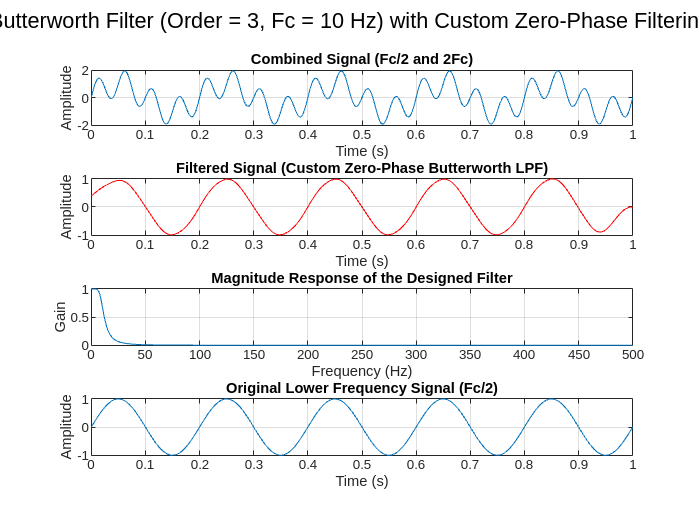

title('Filtered Signal (Custom Zero-Phase Butterworth LPF)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

% Plot Frequency Response of the Filter
[H, W] = freqz(b, a, 1024, Fs);
subplot(4,1,3);
plot(W, abs(H));
title('Magnitude Response of the Designed Filter');
xlabel('Frequency (Hz)');
ylabel('Gain');
grid on;

subplot(4,1,4);
plot(t, signal1);
title('Original Lower Frequency Signal (Fc/2)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

sgtitle('Butterworth Filter (Order = 3, Fc = 10 Hz) with Custom Zero-Phase Filtering');


% ---- Custom Filtering Functions ----
function y = myfilter(b, a, x)
    N = length(x);
    order = length(a);  
    y = zeros(size(x));
    for n = 1:N
        y(n) = b * x(n);
        for k = 2:order
            if (n - k + 1) > 0
                y(n) = y(n) - a(k) * y(n - k + 1);
            end
        end
    end
end

function y = myfiltfilt(b, a, x)
    y_forward = myfilter(b, a, x);
    y_rev = myfilter(b, a, flip(y_forward));
    y = flip(y_rev);
end

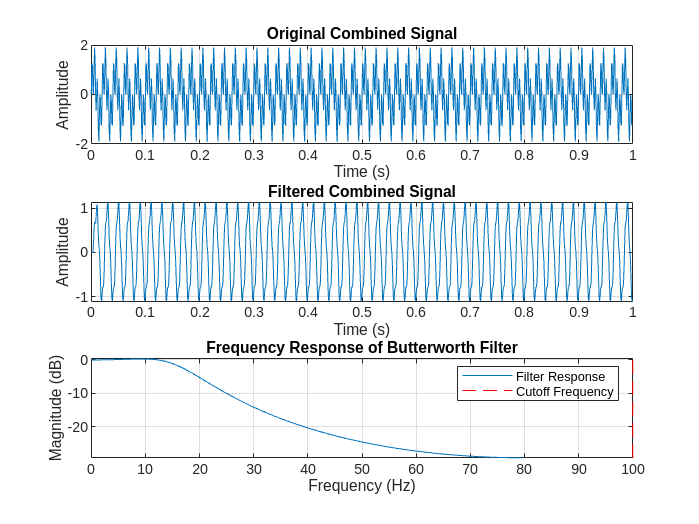

% Manual implementation of 3rd order Butterworth filter
% and signal filtering demonstration

% Design parameters
fc = 100;  % Cutoff frequency in Hz
fs = 1000; % Sampling frequency in Hz
T = 1;     % Total time in seconds
t = 0:1/fs:T-1/fs;  % Time vector

% Generate test signals
f1 = fc/2;    % First frequency (fc/2)
f2 = 2*fc;    % Second frequency (2fc)

% Create individual signals
signal1 = sin(2*pi*f1*t);  % fc/2 signal
signal2 = sin(2*pi*f2*t);  % 2fc signal
combined_signal = signal1 + signal2;  % Combined signal

% Manual Butterworth filter design (3rd order)
% Prototype analog filter poles for 3rd order Butterworth
poles = [
    -0.5 + 0.866i;    % First pole
    -0.5 - 0.866i;    % Second pole
    -1 + 0i           % Third pole
];

% Pre-warp the cutoff frequency
wc = 2*pi*fc;
wa = 2*fs*tan(wc/(2*fs));

% Scale poles by cutoff frequency
s_poles = poles * wa;

% Convert to z-domain using bilinear transform
z_poles = (1 + s_poles/(2*fs))./(1 - s_poles/(2*fs));

% Create transfer function coefficients
[b, a] = zp2tf([], z_poles, 1);

% Normalize the gain at DC
dc_gain = sum(b)/sum(a);
b = b/dc_gain;

% Apply filter to signals
filtered_combined = filter(b, a, combined_signal);
filtered_signal1 = filter(b, a, signal1);
filtered_signal2 = filter(b, a, signal2);

% Plot results
figure;

% Time domain plots
subplot(3,1,1);
plot(t, combined_signal);
title('Original Combined Signal');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

subplot(3,1,2);
plot(t, filtered_combined);
title('Filtered Combined Signal');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

% Frequency response of the filter
[h, w] = freqz(b, a, 1024, fs);
subplot(3,1,3);
plot(w/(2*pi), 20*log10(abs(h)));
title('Frequency Response of Butterworth Filter');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;
hold on;
plot([fc fc], ylim, 'r--');
legend('Filter Response', 'Cutoff Frequency');

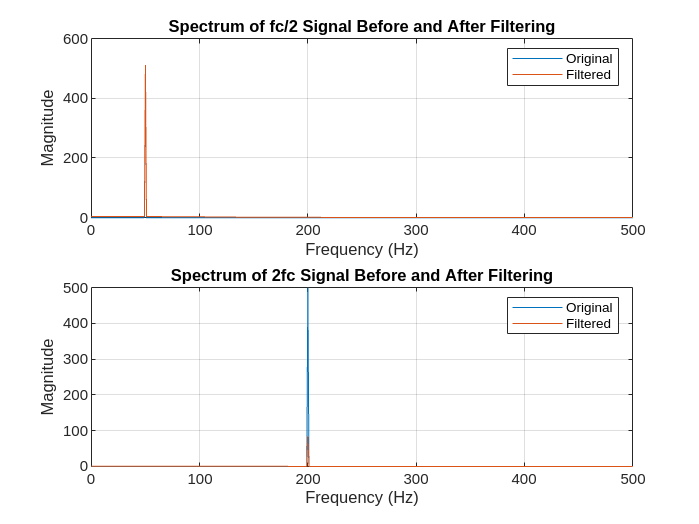


% Calculate and display FFT of signals
N = length(t);
freq = fs*(0:(N/2))/N;

% FFT of original signals
Y1 = fft(signal1);
Y2 = fft(signal2);
P1 = abs(Y1(1:N/2+1));
P2 = abs(Y2(1:N/2+1));

% FFT of filtered signals
Y1_filtered = fft(filtered_signal1);
Y2_filtered = fft(filtered_signal2);
P1_filtered = abs(Y1_filtered(1:N/2+1));
P2_filtered = abs(Y2_filtered(1:N/2+1));

figure;
subplot(2,1,1);
plot(freq, P1(1:N/2+1), freq, P1_filtered(1:N/2+1));
title('Spectrum of fc/2 Signal Before and After Filtering');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
legend('Original', 'Filtered');
grid on;

subplot(2,1,2);
plot(freq, P2(1:N/2+1), freq, P2_filtered(1:N/2+1));
title('Spectrum of 2fc Signal Before and After Filtering');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
legend('Original', 'Filtered');
grid on;